# MATLAB & Simulink workshop

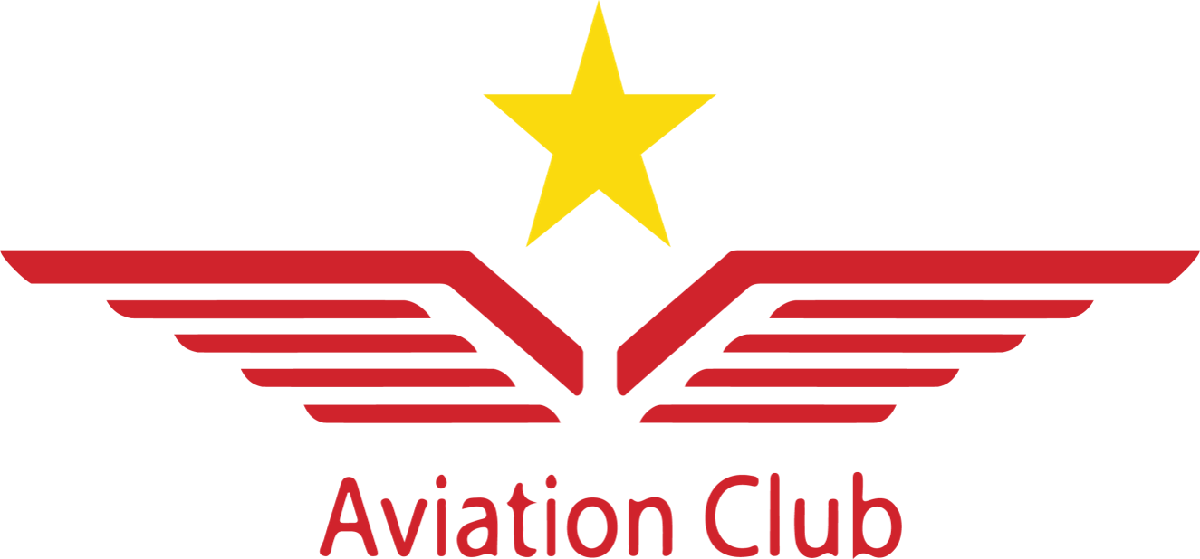

## Session 2: Programming with MATLAB

### Part 1: Variables

Let's start by creating some variables

x1= 3.1

x1 = 3.1000

x2= 4

x2 = 4

y= 's'

y = 's'

z= "hello"

z = "hello"

Special variable ans

3

ans = 3

1+5

ans = 6

Now we check the data type of these variables

class(x1)

ans = 'double'

class(x2)

ans = 'double'

class(y)

ans = 'char'

class(z)

ans = 'string'

How to change the data type of variable

x2=int8(x2);
class(x2)

ans = 'int8'

Overflowing a variable

x=2e10

x = 2.0000e+10

x=int8(x)

x = int8
127

Scalars vs vectors vs matrices 

sc= 1

sc = 1

vec=[1, 1, 1]

vec =      1     1     1


mat=[1 2 3;4 5 6]

mat =      1     2     3
     4     5     6


size function

size(sc)

ans =      1     1


size(vec)

ans =      1     3


size(mat)

ans =      2     3


### Part 2: Operators

Basic arithmetic operators

x=1+2

x = 3

y=2*7

y = 14

z=3^3

z = 27

w=5/2.5

w = 2

Relational operators

a= x==y

a = logical
   0


x>y

ans = logical
   0


y>x

ans = logical
   1


Logical operators

x = 1 && 2

x = logical
   1


x = 1 & 1

x = logical
   1


x1=[1 2 3];
x2=[0 1 1];
%x1 && x2
x1 & x2

ans = 1×3 logical array
   0   1   1


Colon operator

i=1:4

i =      1     2     3     4


i1=1:0.5:3

i1 =     1.0000    1.5000    2.0000    2.5000    3.0000


i2=3:-0.5:1.2

i2 =     3.0000    2.5000    2.0000    1.5000


### Part 3: Control flow

#### Tools to help

Before we get started let's know some functions that will help us later

disp()

disp("hello")

hello


x=3;
disp("my number = " + x)

my number = 3


st="hello";
disp("my word = "+st)

my word = hello


fprintf()

fprintf("hello")

hello

x=3;
fprintf("my number = %.2f",x)

my number = 3.00

st="hello";
fprintf("my word = %s",st)

my word = hello

input()

 %x=input("please enter a number: ")

rem()

 x=rem(3,2)

x = 1

 x=rem(6,5)

x = 1

#### If-statment

basic if-statement (condition) syntax

x=6;
if x==5
    fprintf("x = 5")
end

If-else variation

x=8;
if x==5
    fprintf("x equal 5")
else
    fprintf("x not equal 5")
end

x not equal 5

Nested if and its alternative

x=5; y=5;
% if x==5
%     if y==5
%         fprintf("x and y are equal 5")
%     end
% end
if x==5 && y==5
    fprintf("x and y equal 5")
end

x and y equal 5

elseif statement

x=5;
if x==5
    fprintf("x is equal 5")
elseif x>5
    fprintf("x is greater than 5")
else
    fprintf("x is less than 5")
end

x is equal 5

#### Switch case

Basic example

x=0;
switch x
    case 1
        disp("x=1")
    case 2
        disp("x=2")
    case 3
        disp("x=3")
    otherwise
        disp("x is greater than 3 or smaller than 1")
end

x is greater than 3 or smaller than 1


#### For loops

Basic example

for i=1:10
    fprintf("%d\n",i)
end

1
2
3
4
5
6
7
8
9
10


Pre-made list

list=1:2:9

list =      1     3     5     7     9


for i=list
    fprintf("%d\n",i)
end

1
3
5
7
9


For loop with if conditions

for i=1:10
    if i<=5
        fprintf("first half of th loop\n")
    else
        fprintf("second half of the loop\n")
    end
end

first half of th loop
first half of th loop
first half of th loop
first half of th loop
first half of th loop


second half of the loop
second half of the loop
second half of the loop
second half of the loop
second half of the loop


#### While loop

Basic example

total =0;
counter=0;
while total<50
    counter=counter+1;
    total =total+counter;
end
disp(counter)

    10



disp(total)

    55



total_manual=1+2+3+4+5+6+7+8+9+10

total_manual = 55

### Part 4: problem solving

#### Left-aligned star pyramid

Rows=3;
for i = 1:Rows
    for j = 1:i
        fprintf('*');
    end
    fprintf('\n');
end

******

#### Is leap year

year=1456;
if rem(year,400)==0
    disp("yes")
elseif rem(year,4)==0 && rem(year,100) ~=0
    disp("yes")
else
    disp("No")
end

yes
